[y,fs] = audioread('vaccum_clearner_resampled_44100.wav');

Error using audioread>readaudio (line 143)
The filename specified was not found in the MATLAB path.

Error in audioread (line 136)
    [y, Fs] = readaudio (filename, range, datatype);

a = audioinfo('vaccum_clearner_resampled_44100.wav')

t = linspace(0,7,308700);

figure;
plot(t,y)
title('original siganl')
[imf,residual] = vmd(y);
[a,b] = size(imf);


power

power1 = mean(y.^2);

%Hurst Exponent
for i = 1:5
    
    signal = imf(:,i);
    n = length(signal);
    cum_sum = cumsum(signal - mean(signal));
    
    hurst_exponents = [];
    
    for size = 10:floor(n/2)
        reshaped_data = reshape(cum_sum(1:n - mod(n, size)), [], size);
        
        
        local_trend = mean(reshaped_data, 2);
        hurst_exponents(end+1) = log(mean(sqrt(mean((reshaped_data - local_trend).^2, 2)))) / log(size);
    end
    
   
    fprintf('%f Hurst Exponent: %f\n',i, -mean(hurst_exponents));
end

1.000000 Hurst Exponent: -0.381177
2.000000 Hurst Exponent: -0.391902
3.000000 Hurst Exponent: -0.101845
4.000000 Hurst Exponent: 0.010086
5.000000 Hurst Exponent: 0.127479


<------------------ Noise suppression project --------------> 


-> Step 1: Loading Audio file -----------> Done

-> Step 2: Extracting noise spectrum ----> Done

-> Step 3: Estimating SNR ---------------> Done

-> Step 4: Compute TF attenuation map ---> Done

-> Step 5: Compute Inverse STFT ---------> Done



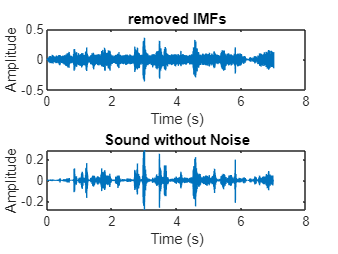

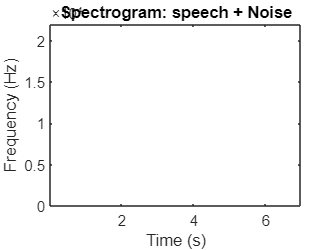

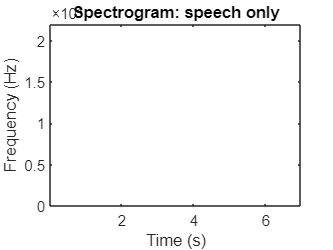

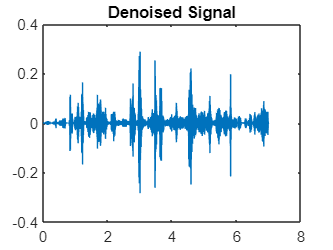

Results displayed.


%signal after hurst exponent classification
sum = imf(:,1)+imf(:,2)+imf(:,3);

project_main(sum)

function project_main(sum)
    fprintf('<------------------ Noise suppression project --------------> \n\n\n')

    % Load audio file
    %[file, path] = uigetfile('.wav', 'Select an audio file');
    %[y, Fe] = audioread("vmdone.wav");
    y = sum;
    Fe = 44100;
    fprintf('-> Step 1: Loading Audio file -----------> Done\n\n');
    
    % Remove the beginning of the sample
    
    
    % Set algorithm parameters
    apriori_SNR = 1;
    alpha = 0.1;
    beta1 = 1;
    beta2 = 1;
    lambda = 2;

    % Set STFT parameters
    NFFT = 1024;
    window_length = round(0.031 * Fe);
    window = hamming(window_length);
    window = window(:);
    overlap = floor(0.45 * window_length);

    % Signal parameters
    t_min = 0.4;
    t_max = 1.00;

    % Construct spectrogram
    [S, F, T] = spectrogram(y + 1i * eps, window, window_length - overlap, NFFT, Fe);
    [Nf, Nw] = size(S);

    % Extract noise spectrum
    t_index = find(T > t_min & T < t_max);
    absS_Noise = abs(S(:, t_index)).^2;
    Noise_spectrum = mean(absS_Noise, 2);
    Noise_specgram = repmat(Noise_spectrum, 1, Nw);
    fprintf('-> Step 2: Extracting noise spectrum ----> Done\n\n');

    % Estimate SNR
    absS = abs(S).^2;
    SNR_est = max((absS ./ Noise_specgram) - 1, 0);
    if apriori_SNR == 1
        SNR_est = filter((1 - alpha), [1 -alpha], SNR_est);
    end

    fprintf('-> Step 3: Estimating SNR ---------------> Done\n\n');

    % Compute attenuation map
    an_lk = max((1 - lambda * ((1 ./ (SNR_est + 1)).^beta1)).^beta2, 0);
    STFT = an_lk .* S;

    fprintf('-> Step 4: Compute TF attenuation map ---> Done\n\n');

    % Compute Inverse STFT
    output_signal = zeros((Nw - 1) * overlap + window_length, 1);
    ind = mod((1:window_length) - 1, Nf) + 1;

    for indice = 1:Nw
        left_index = ((indice - 1) * overlap);
        index = left_index + [1:window_length];
        temp_ifft = real(ifft(STFT(:, indice), NFFT));
        output_signal(index) = output_signal(index) + temp_ifft(ind) .* window;
    end
    
    fprintf('-> Step 5: Compute Inverse STFT ---------> Done\n\n');

    figure;
    subplot(2, 1, 1);
    plot([1:length(y)] / Fe, y);
    xlabel('Time (s)');
    ylabel('Amplitude');
    title('removed IMFs');
    
    subplot(2, 1, 2);
    plot([1:length(output_signal)] / Fe, output_signal);
    xlabel('Time (s)');
    ylabel('Amplitude');
    title('Sound without Noise');
    
    figure;
    S_one_sided = max(S(1:length(F) / 2, :), eps);
    pcolor(T, F(1:end/2), 10 * log10(abs(S_one_sided)));
    shading interp;
    colormap('hot');
    title('Spectrogram: speech + Noise');
    xlabel('Time (s)');
    ylabel('Frequency (Hz)');
    
    figure;
    S_one_sided = max(STFT(1:length(F) / 2, :), eps);
    pcolor(T, F(1:end/2), 10 * log10(abs(S_one_sided)));
    shading interp;
    colormap('hot');
    title('Spectrogram: speech only');
    xlabel('Time (s)');
    ylabel('Frequency (Hz)');

    time = (1:length(output_signal)) / Fe;
    
    figure;
    plot(time, output_signal(:, 1));
    title('Denoised Signal');

    comap = [y;output_signal];
    sound(comap, Fe)
    audiowrite('test2_result.wav',output_signal,Fe)
    fprintf('Results displayed.\n');
end

erg